load 5FoldCV-3-6-9.mat

%Train SVM using a linear kernel
%Do 5-Fold Cross Validation
model=fitcsvm(digitNormalize.',class_369.','KernelFunction','linear','CVPartition',cvp_369);
model.ScoreTransform='logit';

%%ROC and AUC
[predict_label,score]=kfoldPredict(model);

%compute accuracy 
accur=zeros(1,5);
accur(1,1)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 2 3 4]);
accur(1,2)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 2 3 5]);
accur(1,3)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 2 4 5]);
accur(1,4)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 3 4 5]);
accur(1,5)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[2 3 4 5]);
disp(accur)

    0.9586    0.9603    0.9597    0.9564    0.9583




figure(1)
confusionchart(class_369.',predict_label);
Title = sprintf('Confusion Matrix of SVM with linear kernel (Acc = %.2f%%)',mean(accur)*100);
sgtitle(Title);
xlabel('Prediction');ylabel('Ground Truth')

figure(2)
[FPR_Linear,TPR_Linear,T,AUC]=perfcurve(class_369.',predict_label,1);
disp(AUC);

    0.9545



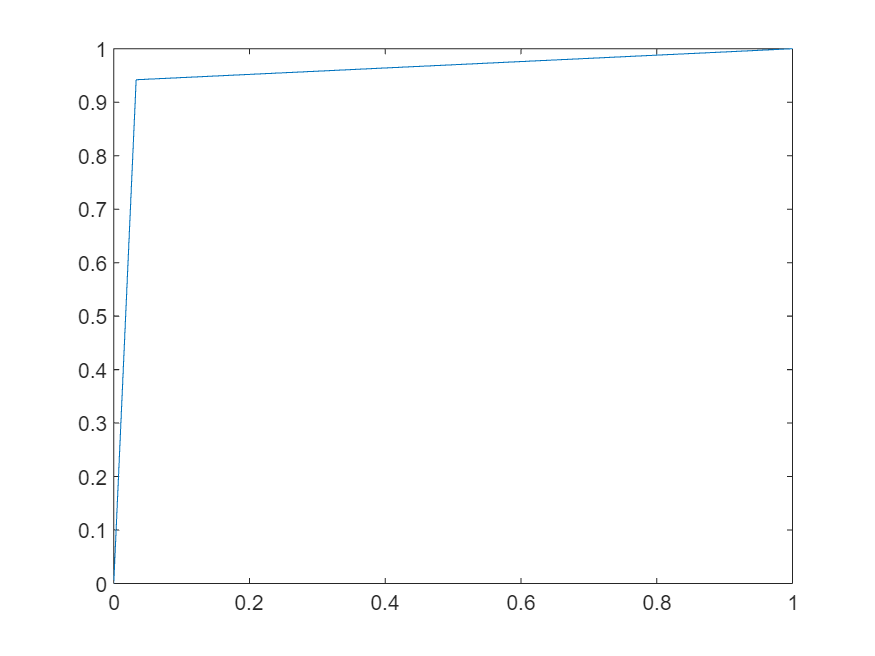

plot(FPR_Linear,TPR_Linear)

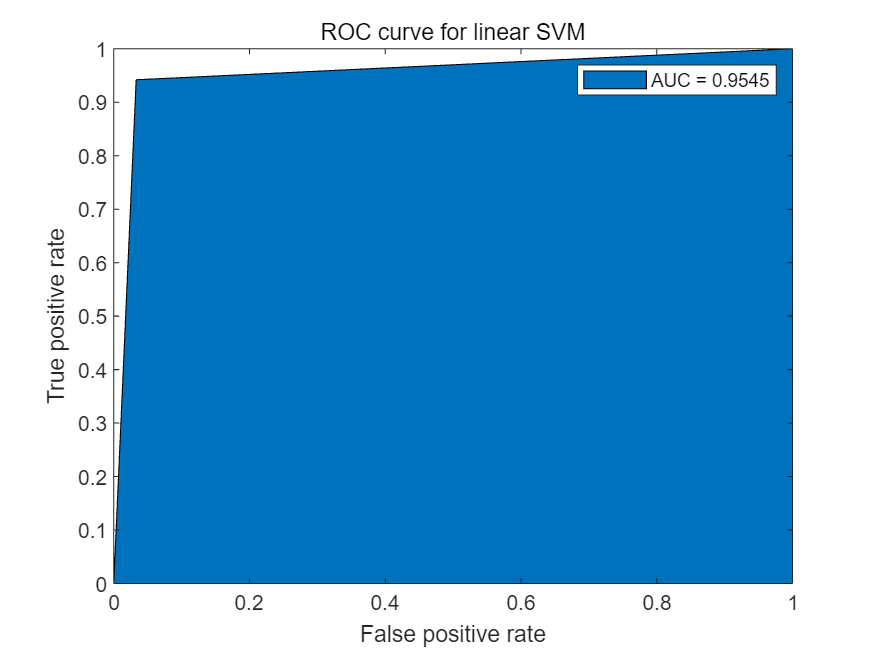

area(FPR_Linear, TPR_Linear);
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve for linear SVM')
legend(['AUC = ', num2str(AUC)]);
box on

%save svm_linear_result